simTime = 15;
zDomain = quantity.Domain("z", linspace(0, 1, 101));
tDomain = quantity.Domain("t", linspace(0, simTime, 2001));
syms z t;
Lambda = quantity.Symbolic(diag([1, -1]), zDomain, "name", "Lambda");
A = quantity.Symbolic([0, 0; 0, 0], zDomain, "name", "A");
Q0 = 0;
Q1 = 1;

output = model.Output("controlOutput", "C0", [1 0]);
% G1 = [0, 0; 0, 0]*quantity.Symbolic(1 + z, zDomain, "name", "G1");
% G2 = [0, 0];
% G3 = [1, 0];
% G4 = [0, 0];
G1 = [0; 0]*quantity.Symbolic(1 + z, zDomain, "name", "G1");
G2 = [0];
G3 = [1];
G4 = [0];

S = 0;
P = 1;
% S = [0 1; -1 0];
% P = eye(2);
distOde = ss(S, zeros(size(S,1)), P, []);
v = stateSpace.simulate(distOde, zeros(size(S,1), length(tDomain.grid)), tDomain.grid, ones(size(S,1),1));
v = quantity.Discrete(v, tDomain);

S_r = [0 1; -1 0];
P_r = [1 0];
zeroSig = quantity.Discrete.zeros([size(S,1), 1], tDomain);

simulationSetting = {'t', tDomain.grid};
ic = {};
for indAgent = 1:3
    ic{end+1} = "agent"+indAgent+".x";
    ic{end+1} = quantity.Symbolic(zeros(size(Lambda,1),1), zDomain);
    ic{end+1} = "agent"+indAgent+"observer.x";
    ic{end+1} = quantity.Symbolic(zeros(size(Lambda,1),1), zDomain);
end

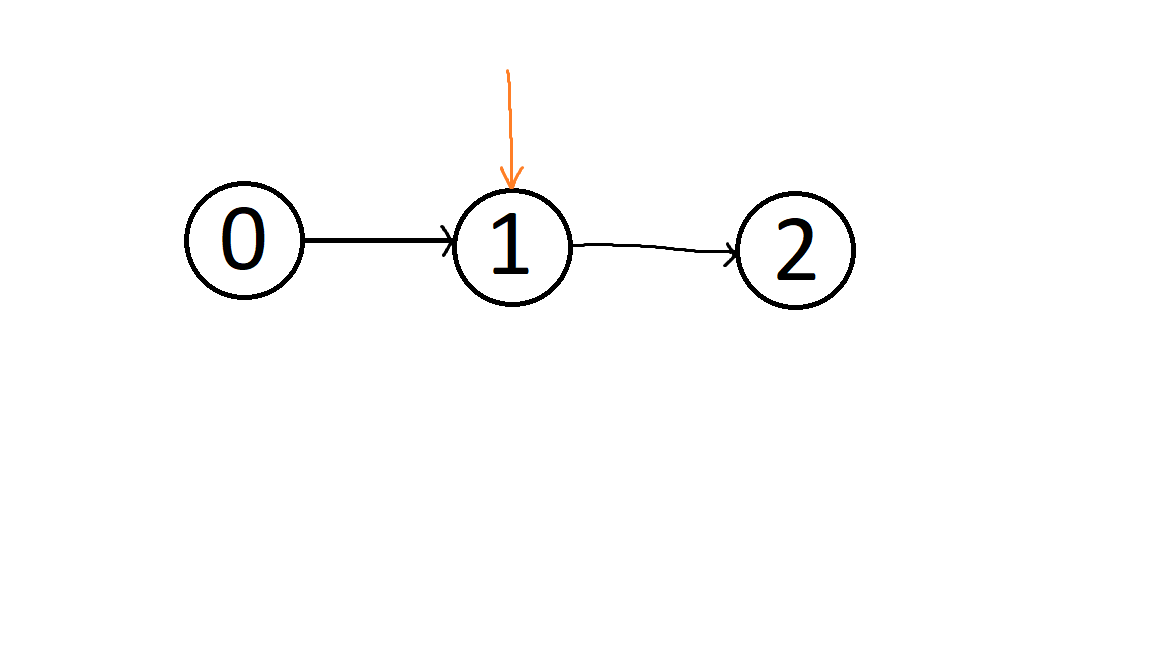

adjacencyMatrix = [0 0 0 ; 1 0 0 ; 0 1 0 ];
mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, "Q0", Q0, "Q1", Q1,...
    "G1", G1, "G2", G2, "G3", G3, "G4", G4);
[systemTarget, controller] = mas.feedforwardControl(S_r, P_r, S, P);

## compute a new backstepping kernel ... 
### Set lines of characteristics of :  100.0 
 Elapsed time 0.99 seconds 
### Successive approximations of kernel : Finished 4 of max. 30 steps, change: 0, tolerance: 0.001

 Elapsed time 7.93 seconds 


distObserver = DisturbanceObserver(mas, S, P, "c_", 6);

## compute a new backstepping kernel ... 
### Set lines of characteristics of :  100.0 
 Elapsed time 0.96 seconds 
### Successive approximations of kernel : Finished 4 of max. 30 steps, change: 0, tolerance: 0.001

 Elapsed time 8.03 seconds 
Successive Calculation of inverse of c flip({flip(Lambda)^{-1}  flip(Lambda)}^{T}):  0 of max. 50 
 Elapsed time 0.10 seconds 


exogenousSignals = {"disturbance", [zeroSig; v; zeroSig]};
simData = mas.simulate(simulationSetting, ic, controller, {"disturbance", [zeroSig; v; zeroSig]}, distObserver, true);

Error using model.Transport/getClosedLoopSimulationModel (line 727)
only the case that all inputTypes are used for networked control is implemented yet

Error in model.Network/getAgentStateSpace (line 234)
				agentSsCell{it} = obj.agent(it).getClosedLoopSimulationModel(...

Error in 

mas.plotOutput(simData);

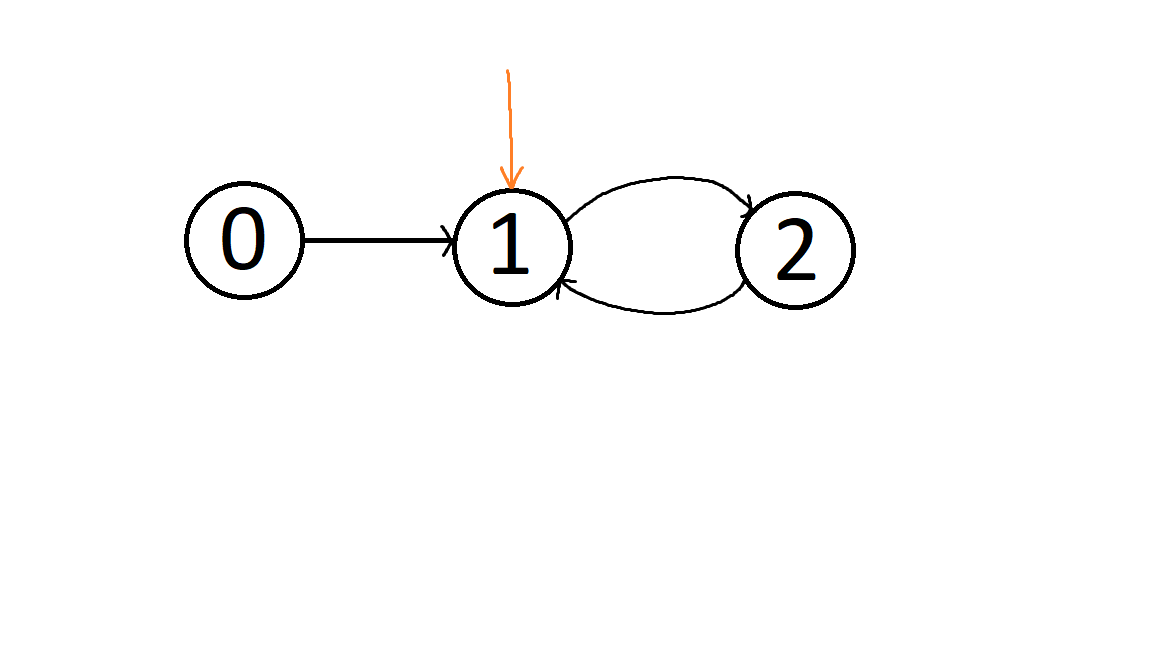

adjacencyMatrix = [0 0 0 ; 1 0 1 ; 0 1 0 ];
mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, "Q0", Q0, "Q1", Q1,...
    "G1", G1, "G2", G2, "G3", G3, "G4", G4);
[systemTarget, controller] = mas.feedforwardControl(S_r, P_r, S, P);
distObserver = DisturbanceObserver(mas, S, P, "c_", 6);
exogenousSignals = {"disturbance", [zeroSig; v; zeroSig]};
simData = mas.simulate(simulationSetting, ic, controller, exogenousSignals, distObserver, true);
mas.plotOutput(simData);

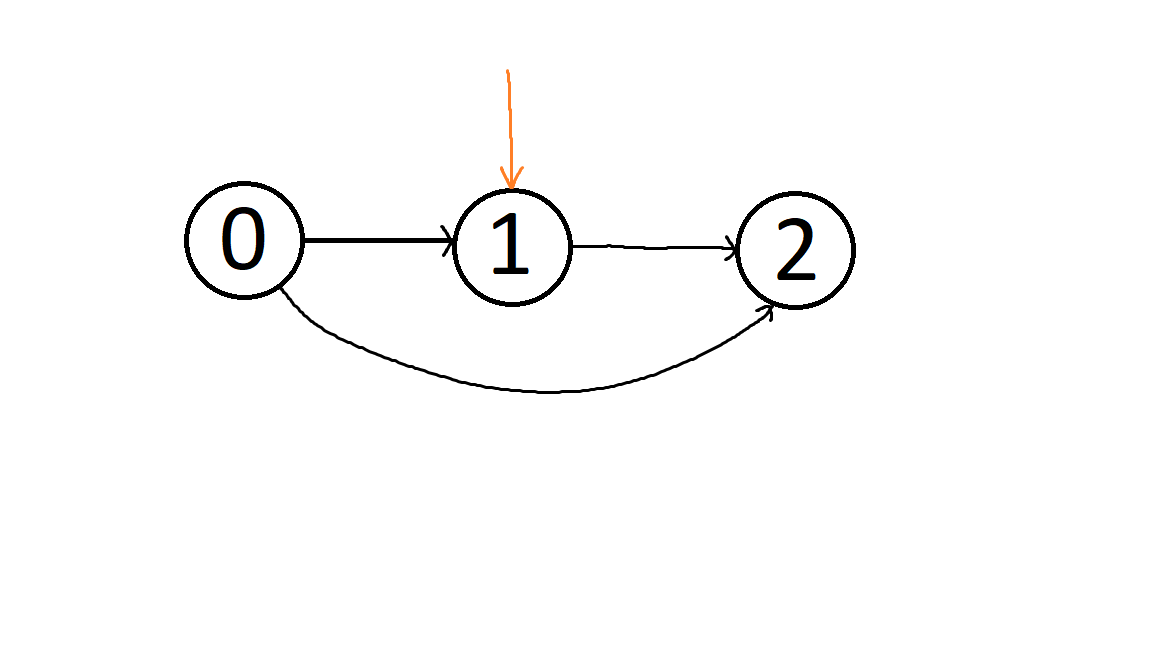

adjacencyMatrix = [0 0 0 ; 1 0 0 ; 1 1 0 ];
mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, "Q0", Q0, "Q1", Q1,...
    "G1", G1, "G2", G2, "G3", G3, "G4", G4);
[systemTarget, controller] = mas.feedforwardControl(S_r, P_r, S, P);
distObserver = DisturbanceObserver(mas, S, P, "c_", 6);
exogenousSignals = {"disturbance", [zeroSig; v; zeroSig]};
simData = mas.simulate(simulationSetting, ic, controller, exogenousSignals, distObserver, true);
mas.plotOutput(simData);

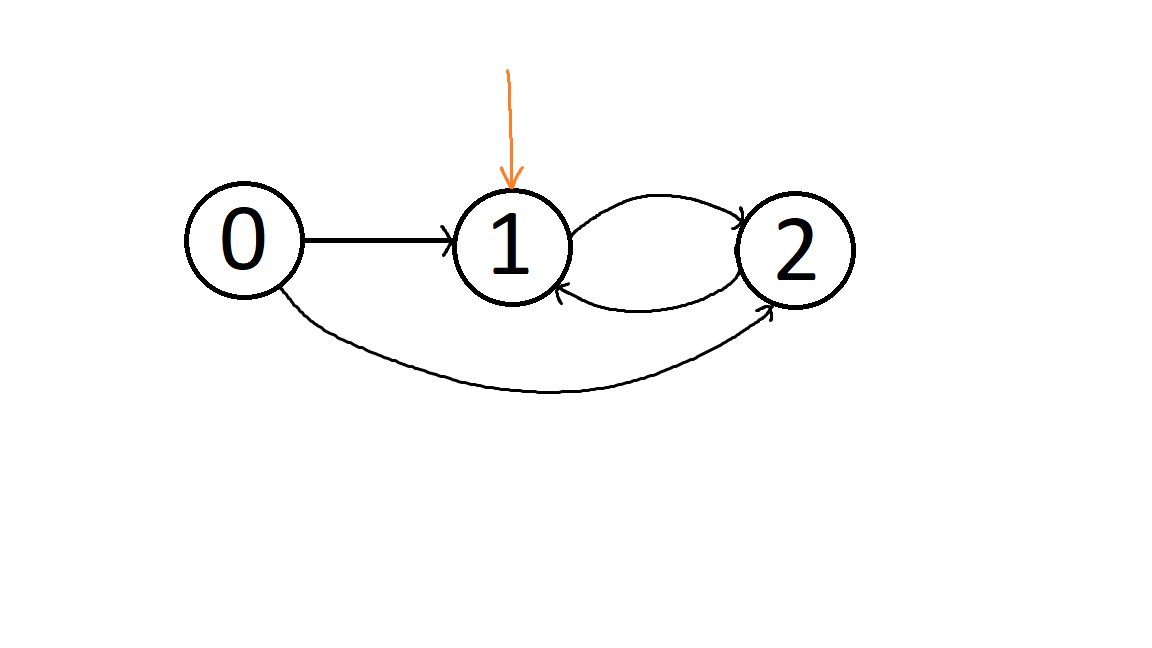

adjacencyMatrix = [0 0 0 ; 1 0 1 ; 1 1 0 ];
mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, "Q0", Q0, "Q1", Q1,...
    "G1", G1, "G2", G2, "G3", G3, "G4", G4);
[systemTarget, controller] = mas.feedforwardControl(S_r, P_r, S, P);
distObserver = DisturbanceObserver(mas, S, P, "c_", 6);
exogenousSignals = {"disturbance", [zeroSig; v; zeroSig]};
simData = mas.simulate(simulationSetting, ic, controller, exogenousSignals, distObserver, true);
mas.plotOutput(simData);

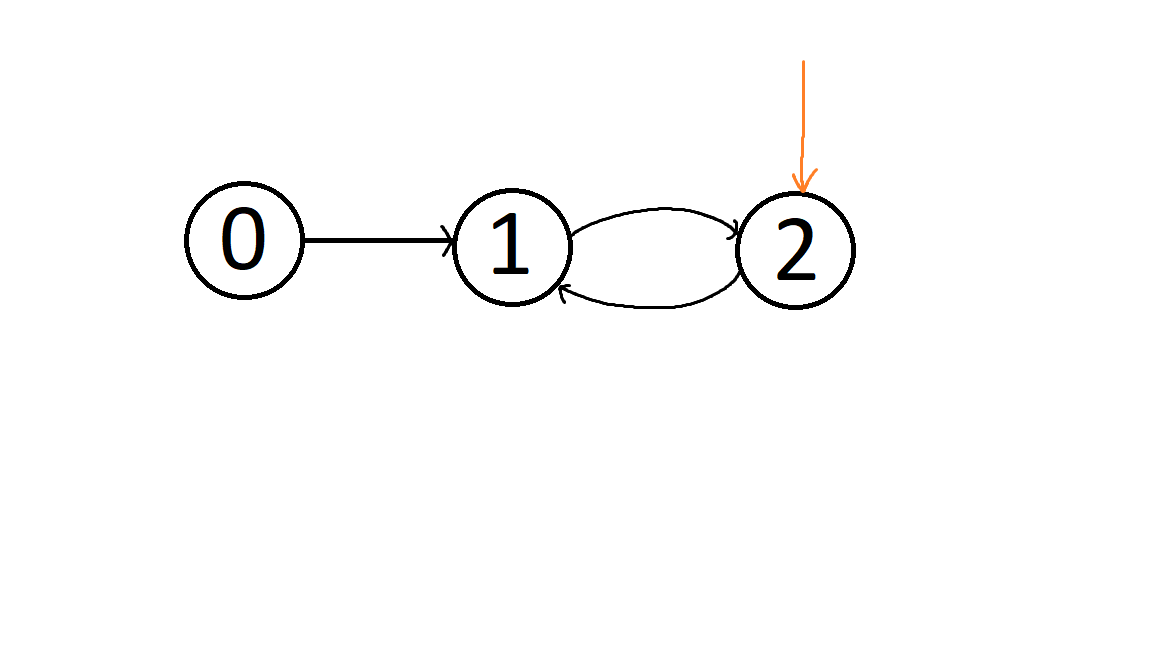

adjacencyMatrix = [0 0 0 ; 1 0 1 ; 0 1 0 ];
mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, "Q0", Q0, "Q1", Q1,...
    "G1", G1, "G2", G2, "G3", G3, "G4", G4);
[systemTarget, controller] = mas.feedforwardControl(S_r, P_r, S, P);
distObserver = DisturbanceObserver(mas, S, P, "c_", 6);
exogenousSignals = {"disturbance", [zeroSig; zeroSig; v]};
simData = mas.simulate(simulationSetting, ic, controller, exogenousSignals, distObserver, true);
mas.plotOutput(simData);

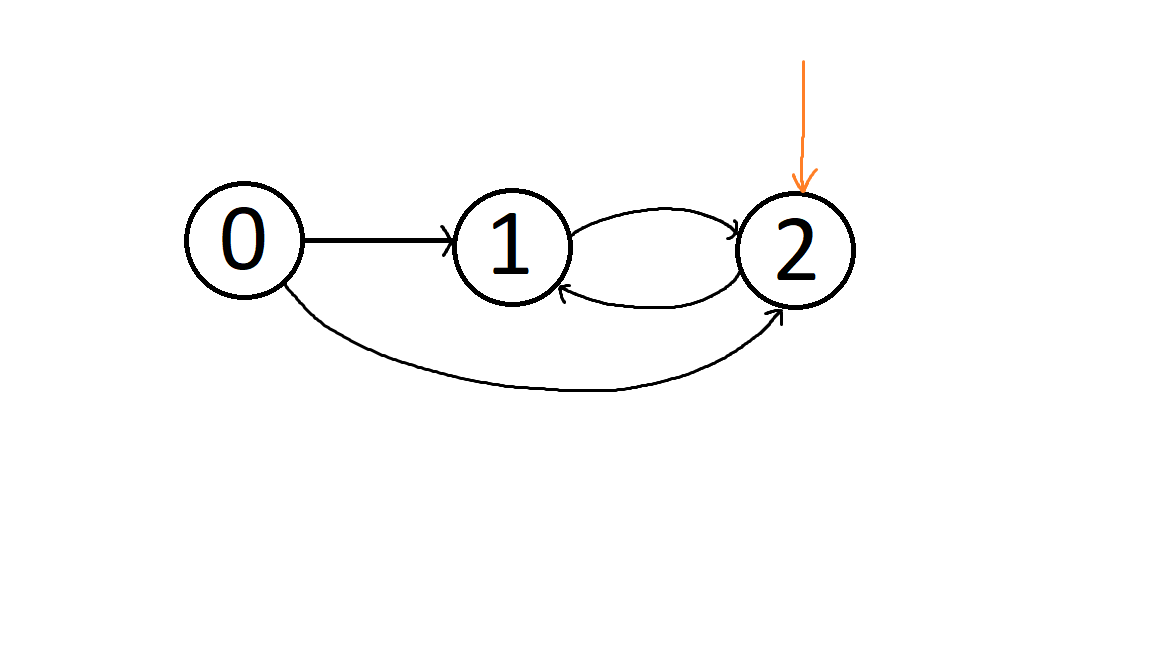

adjacencyMatrix = [0 0 0 ; 1 0 1 ; 1 1 0 ];
mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, "Q0", Q0, "Q1", Q1,...
    "G1", G1, "G2", G2, "G3", G3, "G4", G4);
[systemTarget, controller] = mas.feedforwardControl(S_r, P_r, S, P);
distObserver = DisturbanceObserver(mas, S, P, "c_", 6);
exogenousSignals = {"disturbance", [zeroSig; zeroSig; v]};
simData = mas.simulate(simulationSetting, ic, controller, exogenousSignals, distObserver, true);
mas.plotOutput(simData);

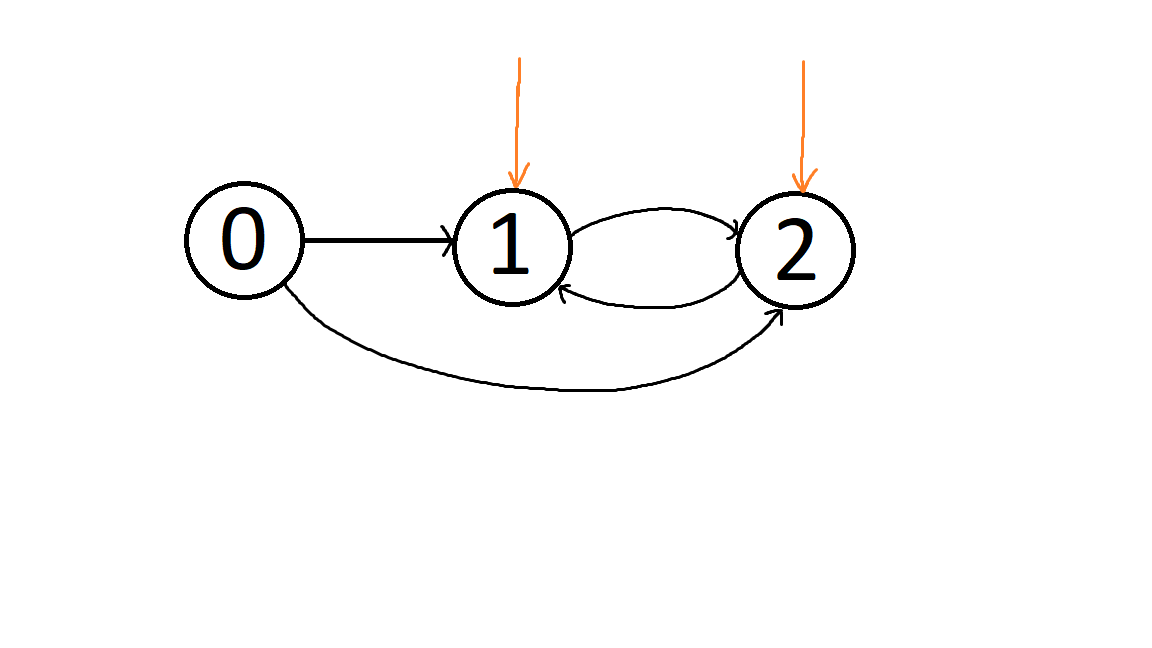

adjacencyMatrix = [0 0 0 ; 1 0 1 ; 1 1 0 ];
mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, "Q0", Q0, "Q1", Q1,...
    "G1", G1, "G2", G2, "G3", G3, "G4", G4);
[systemTarget, controller] = mas.feedforwardControl(S_r, P_r, S, P);
distObserver = DisturbanceObserver(mas, S, P, "c_", 6);
exogenousSignals = {"disturbance", [zeroSig; v; v]};
simData = mas.simulate(simulationSetting, ic, controller, exogenousSignals, distObserver, true);
mas.plotOutput(simData);